# Determine Underlying Probability Distribution

Generate 5,000 normally distributed random numbers with a mean of 5 and a standard deviation of 2. Plot a histogram with `Normalization` set to `'pdf'` to produce an estimation of the probability density function.

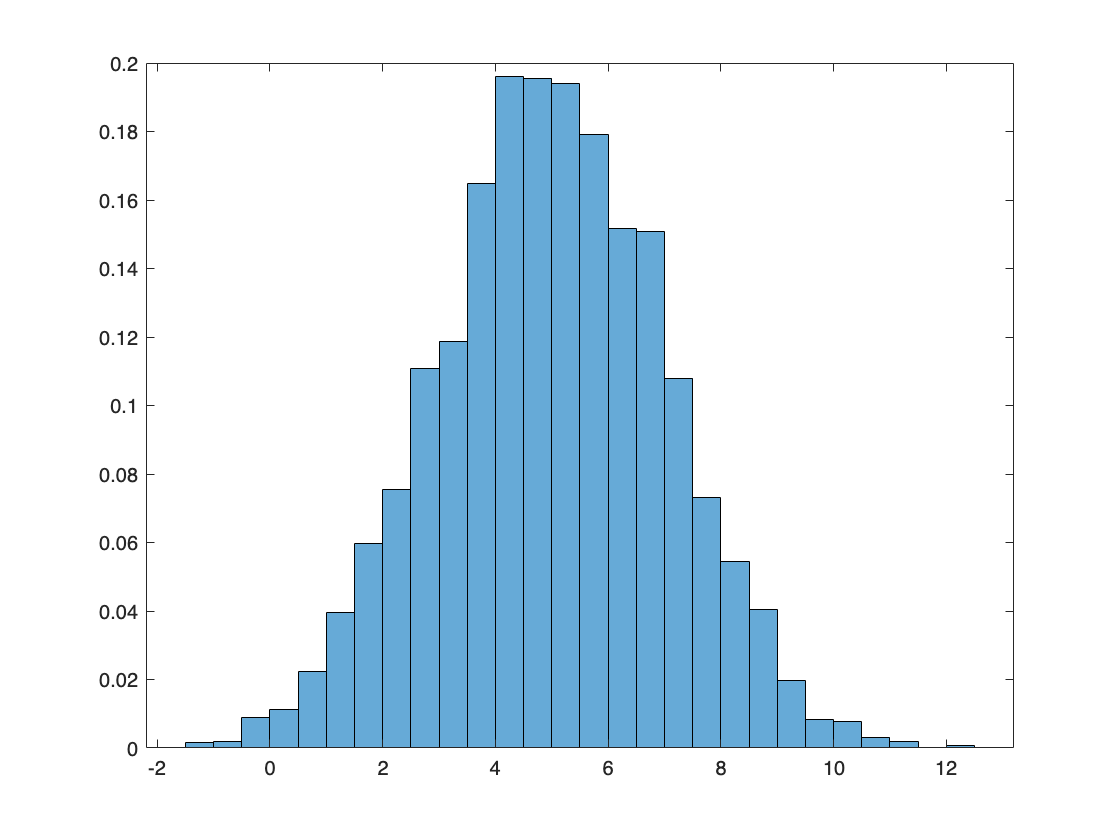

x = 2*randn(5000,1) + 5;
histogram(x,'Normalization','pdf')

In this example, the underlying distribution for the normally distributed data is known. You can, however, use the `'pdf'` histogram plot to determine the underlying probability distribution of the data by comparing it against a known probability density function.

The probability density function for a normal distribution with mean $\mu$, standard deviation $\sigma$, and variance $\sigma^2$ is


$$f(x,\mu,\sigma) = \frac{1}{\sigma \sqrt{2 \pi}} \mbox{ exp}
\left[-\frac{(x-\mu)^2}{2\sigma^2}\right].$$


Overlay a plot of the probability density function for a normal distribution with a mean of 5 and a standard deviation of 2.

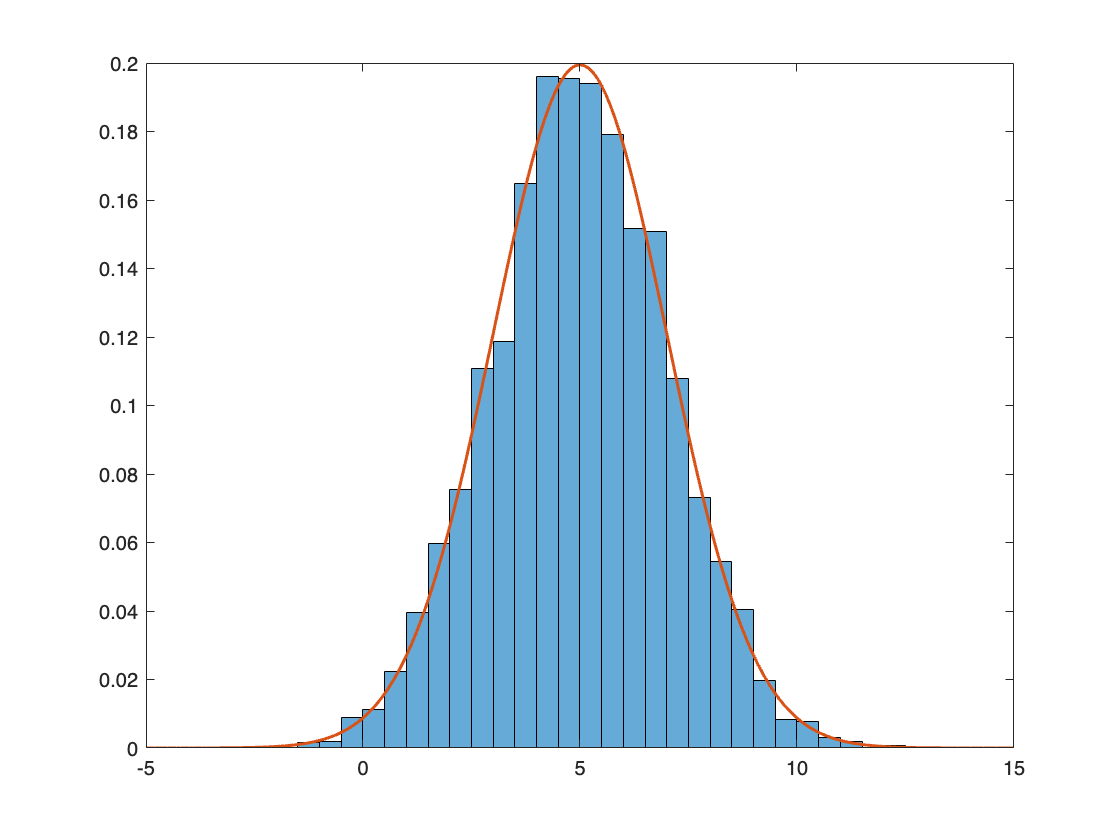

hold on
y = -5:0.1:15;
mu = 5;
sigma = 2;
f = exp(-(y-mu).^2./(2*sigma^2))./(sigma*sqrt(2*pi));
plot(y,f,'LineWidth',1.5)

*Copyright 2015 The MathWorks, Inc.*